% Netflix movie data

## Load Movie data

load data/ex8_movies.mat
Ytrue = Y;
clear Y;
[n,s] = size(Ytrue);
disp(n)

        1682



disp(s)

   943



disp('job done')

job done


% s = size(Y,2); %num data points
% F = 6;
% frames = floor(linspace(1,size(Y,3)-1,F)); %even spacing between frames
% n = 2*F;
% Ytrue = reshape(permute(Y(1:2,:,frames),[1 3 2]),n,s);
% disp("done")

## Verify data is low-rank in lifted domain

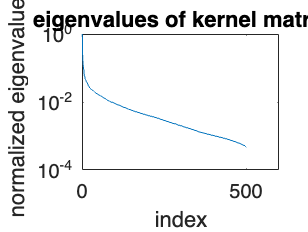

K = (Ytrue*Ytrue').^2;
[V,S] = rsvdpsd(K,500,3,2);
figure(1);
ev = sort(diag(S),'descend');
semilogy(ev/ev(1)); title('eigenvalues of kernel matrix'); ylabel('normalized eigenvalues'); xlabel('index');

disp('job done, yea')

job done, yea


## Subsample data uniformly at random

rng(10); %fix random seedf
missrate = 0.1;
rind = randperm(n*s);
rv = round((1-missrate)*n*s);
sampmask = false(s,n);
sampmask(rind(1:rv)) = true;

samples = Ytrue(sampmask);
Yinit = zeros(s,n);
Yinit(sampmask) = samples;
disp('job done, yes')

job done, yes


## Run low-rank matrix completion (LRMC)

options_nn.lambda = 1e8;
options_nn.mu = 1;
options_nn.niter = 200;
Ylrmc = lrmc_admm(Yinit,sampmask,samples,options_nn);
fprintf('LRMC NRMSE = %1.2e\n',norm(Ylrmc-Ytrue,'fro')/norm(Ytrue,'fro'));
disp('job done, yeah')

## Run variety-based matrix completion (VMC)

options = [];
options.d = 3; %kernel degree
options.niter = 500;
options.eigcomp = 'kernel-rsvd';
options.rmax = 200;
options.eigtol = 1e-6; %keep small for stable convergence
options.gamma0 = 1;

% reduce number of iterations for faster runtime
tic;
[Yvmc,cost,update,error] = vmc(Yinit,sampmask,samples,options,Ytrue);

Arrays have incompatible sizes for this operation.

Error in vmc (line 225)
    error(1) = norm(X-Xtrue,'fro')/norm(Xtrue,'fro');

Related documentation

toc;

fprintf('VMC NRMSE = %1.2e\n',norm(Yvmc-Ytrue,'fro')/norm(Ytrue,'fro'));

figure(1);
subplot(2,2,1);
semilogy(cost); title('cost/iter'); ylabel('cost'); xlabel('iter');
subplot(2,2,2);
semilogy(error); title('error/iter'); ylabel('NRMSE'); xlabel('iter');
subplot(2,2,3);
semilogy(update); title('update/iter'); ylabel('NRMSE'); xlabel('iter');
disp('job done')

## Display columnwise errors

figure(2);
colerr_vmc = zeros(1,s);
colerr_lrmc = zeros(1,s);
for j = 1:s
    colerr_vmc(j) = norm(Xvmc(:,j)-Xtrue(:,j))/norm(Xtrue(:,j));
    colerr_lrmc(j) = norm(Xlrmc(:,j)-Xtrue(:,j))/norm(Xtrue(:,j));
end
[colerr_vmc,idx] = sort(colerr_vmc,'descend');
[colerr_lrmc,idx] = sort(colerr_lrmc,'descend');
errthresh = 1e-2;

subplot(2,1,1);
semilogy(colerr_lrmc,'.-'); title('LRMC sorted column errors');
hold on
line([0 s],[errthresh errthresh],'Color','red');
hold off
axis([1 s 1e-6 10]);
legend('col.error','threshold');
subplot(2,1,2);
semilogy(colerr_vmc,'.-'); title('VMC sorted column errors');
hold on
line([0 s],[errthresh errthresh],'Color','red');
hold off
legend('col.error','threshold');
axis([1 s 1e-6 10]);
fprintf('LRMC recovered %2.1f%% columns (%d of %d) with err < %1.1e\n',(nnz(colerr_lrmc < errthresh)/s)*100,nnz(colerr_lrmc < errthresh),s,errthresh);
fprintf('VMC recovered %2.1f%% columns (%d of %d) with err < %1.1e\n',(nnz(colerr_vmc < errthresh)/s)*100,nnz(colerr_vmc < errthresh),s,errthresh);
disp('job done')

